# Thermoeconomic Analysis Demo

Use ThermoeconomicAnalysis function to compute the exergy cost of a plant

#### Select and check the model file

filename="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(filename);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(3));
Samples=convertCharsToStrings(data.ResourceSamples);
ResourceSample=convertStringsToChars(Samples(1));
CostTables='ALL';

#### Compute Cost Analysis

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample);

#### Show Results

printResults(res);

Process Exergy Cost

Key        P*(kW)     Pe*(kW)     Pr*(kW)      F*(kW)      R*(kW)
——————————————————————————————————————————————————————————————————
BLR       137.698      90.040      47.658      90.040      47.658
TRB        95.903      61.174      34.729      94.583       1.321
IHE         5.929       3.389       2.539       5.240       0.689
PMP         6.609       3.740       2.869       5.863       0.746
CND        50.413      32.606      17.807      50.413       0.000


Process Unit Exergy Cost

Key      kP*(J/J)   kPe*(J/J)   kPr*(J/J)    kF*(J/J)    kR*(J/J)      k(J/J)
——————————————————————————————————————————————————————————————————————————————
BLR        1.9680      1.2868      0.6811      1.0000      0.6811      1.2868
TRB        2.5471      1.6247      0.9224      2.0232      0.0351      1.2416
IHE        2.5777      1.4735      1.1041      2.0232      0.2994      1.1261
PMP        3.3245      1.8813      1.4431      2.5471      0.3751      1.1579
CND        2.0232  

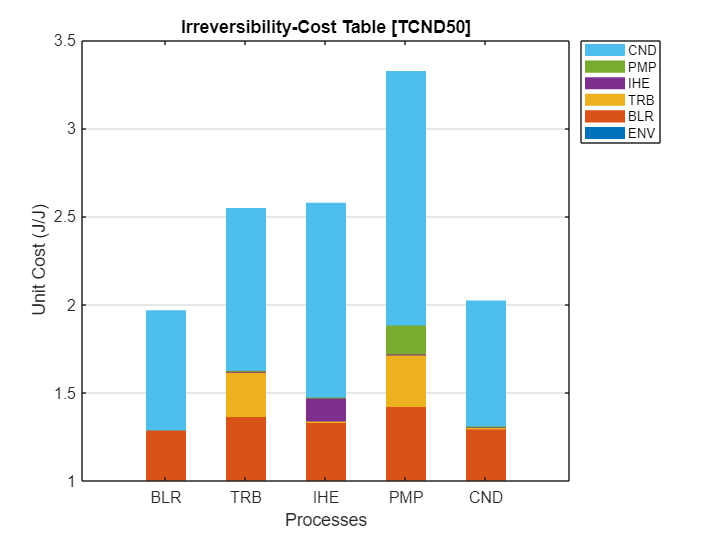

showGraph(res);